syms x y z dx dy dz sigma

N = 6; %number of nodes
s = 3; %number of dimensions

Xi = [x y z] %The x variable of 1 node

$$Xi = \left(\begin{array}{ccc} x & y & z \end{array}\right)$$

X_sys = repmat(Xi,N,1)

$$X\_sys = \left(\begin{array}{ccc} x & y & z\\ x & y & z\\ x & y & z\\ x & y & z\\ x & y & z\\ x & y & z \end{array}\right)$$



%connectivity matrices
% with zero-row sums and nonnegative off-diagonal elements cij = cji, dij = dji, and gij = gji
m =[1 2;
    2 3;
    3 4;
    3 5;
    4 6;
    5 6;]; %connections
C = create_laplacian(N,m) %creating the laplacian matrix

C =      1    -1     0     0     0     0
    -1     2    -1     0     0     0
     0    -1     3    -1    -1     0
     0     0    -1     2     0    -1
     0     0    -1     0     2    -1
     0     0     0    -1    -1     2



%creating the connectivity matrix D
m = [2 3];
D = create_laplacian(N,m)

D =      0     0     0     0     0     0
     0     1    -1     0     0     0
     0    -1     1     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



%creating the connectivity matrix G
G = zeros(N,N);

%inner matrices 
P = diag([1, 0, 0 ]);
L = diag([0, 1, 0]);
M = diag([0, 0, 1]);



%Initializing the problem
sigma = 10;
r = 28;
b = 8/3;
dt = 0.01;

x  = [1:N]';
dx = zeros(N,1);
y  = zeros(N,1) + 1;
dy = zeros(N,1);
z  = zeros(N,1) + 1;
dz = zeros(N,1);

for k = 1 : 2000
    for i = 1:N
        c = 0;
        d = 0;
        for j = 1:N 
            %computing the interlayer connections
            c = c + C(i,j)*x(j);
            d = d + D(i,j)*y(j);
        end
        dx(i) = sigma*(y(i)-x(i)) + c;
        dy(i) = r*x(i) - y(i) - x(i)*z(i) + d;
        dz(i) = -b*z(i) + x(i)*y(i);
    end
    x = x + dx*dt;
    y = y + dy*dt;
    z = z + dz*dt;
end
x

x =     9.2794
  -16.1113
   14.3352
   14.2148
   12.6732
  -13.8799


y

y =    12.2266
   -3.3697
   -4.3841
    3.2542
   10.1681
  -13.1837


z

z =    19.3929
   40.5124
   43.1206
   39.8909
   32.2408
   27.0481


N = 6;
m =[1 2;
    2 3;
    3 4;
    3 5;
    4 6;
    5 6;]; %connections
C = create_laplacian(N,m)*100 %creating the laplacian matrix

C =    100  -100     0     0     0     0
  -100   200  -100     0     0     0
     0  -100   300  -100  -100     0
     0     0  -100   200     0  -100
     0     0  -100     0   200  -100
     0     0     0  -100  -100   200



sigma = 10;
r = 28;
b = 8/3;

f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)) - C*x(1:N);
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N);
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N);
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N))-C*x(1:N);r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


tspan = [0 100];
x0 = randn(3*N,1)*10

x0 =    -0.0685
   15.3263
   -7.6967
    3.7138
   -2.2558
   11.1736
  -10.8906
    0.3256
    5.5253
   11.0061


[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0)

T =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001


X =    -0.0685   15.3263   -7.6967    3.7138   -2.2558   11.1736  -10.8906    0.3256    5.5253   11.0061   15.4421    0.8593  -14.9159   -7.4230  -10.6158   23.5046   -6.1560    7.4808
   -0.0651   15.3167   -7.6868    3.7130   -2.2535   11.1683  -10.8906    0.3269    5.5245   11.0061   15.4419    0.8599  -14.9158   -7.4230  -10.6159   23.5045   -6.1561    7.4807
   -0.0616   15.3071   -7.6769    3.7122   -2.2512   11.1630  -10.8906    0.3282    5.5238   11.0061   15.4417    0.8604  -14.9157   -7.4229  -10.6159   23.5045   -6.1561    7.4807
   -0.0582   15.2975   -7.6670    3.7115   -2.2488   11.1578  -10.8906    0.3295    5.5231   11.0061   15.4415    0.8610  -14.9156   -7.4228  -10.6159   23.5044   -6.1562    7.4807
   -0.0548   15.2880   -7.6571    3.7107   -2.2465   11.1525  -10.8906    0.3308    5.5224   11.0062   15.4412    0.8615  -14.9155   -7.4228  -10.6160   23.5044   -6.1562    7.4807
   -0.0377   15.2403   -7.6079    3.7069   -2.2347   11.1263  -10.8905    0.3373    5.5188 

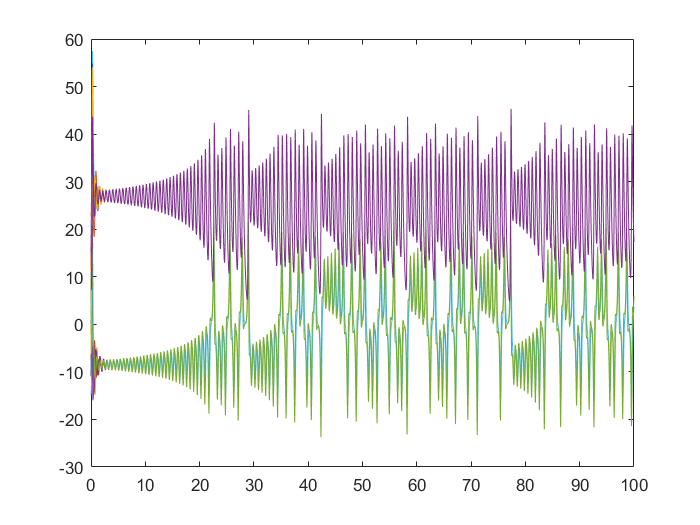

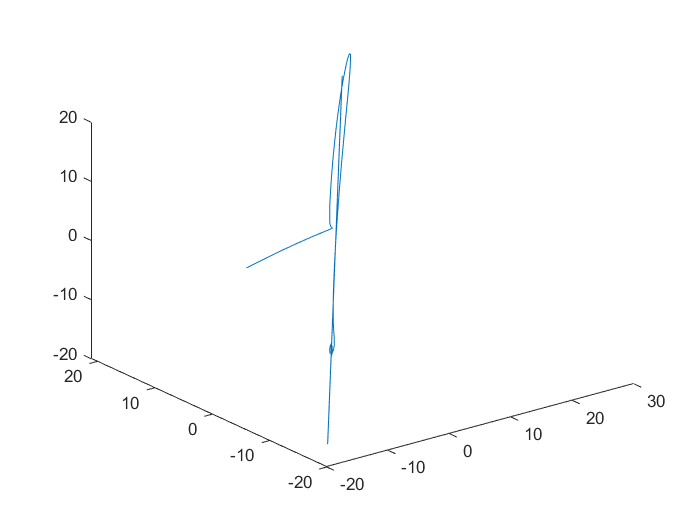

figure
clf
plot(T,X)